# Fundamentals of Linear Control

**Mauricio de Oliveira**

*Supplemental material **for Chapter 7*

## Before You Start

In this script you will perform calculations with transfer-functions. In addition to the commands already used, the following MATLAB commands will be used:

- `bode`, to calculate the frequency response;

- `nyquist`, to calculate the Nyquist plot;

- `margin`, to calculate gain and phase margins

- `norm`, to calculate the stability margin.

 You will also use the following auxiliary commands:

- `basym`, provided as an auxiliary mfile, to plot the asymptotes of a bode plot;

- `arrow`, provided as an auxiliary mfile, to add arrows to Nyquist plots.

## 7.1 Bode Plots

Create a `tf` object to represent the controller $C_\mathrm{lead}$from (6.17):

w1 = 7.5;
w2 = 21;
K = 3.83;
Clead = K * tf([1 w1], [1 w2])


Clead =
 
  3.83 s + 28.73
  --------------
      s + 21
 
Continuous-time transfer function.



zpk(Clead)


ans =
 
  3.83 (s+7.5)
  ------------
     (s+21)
 
Continuous-time zero/pole/gain model.



and use the provided `basym` function and `bode` to plot the Bode plot and the straight line asymptotes of the magnitude of the frequency response:

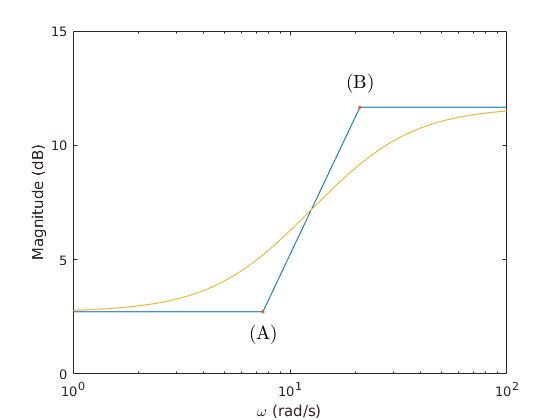

% Fig. 7.5:
figure()

w = logspace(-1,3,300);
[mag,phs] = bode(Clead, w);
[wl,magl,wp,phsl] = basym(Clead);

xl = 10.^[0 2];
yl = [0 15];

semilogx(wl, magl, '-', wl,magl, '.', ...
         w, 20*log10([mag(:)']))

text(w1, magl(2)-1, '(A)', 'BackgroundColor', 'white', 'FontSize', 14, 'HorizontalAlignment', 'center','interpreter','latex');
text(w2, magl(4)+1, '(B)', 'BackgroundColor', 'white', 'FontSize', 14, 'HorizontalAlignment', 'center','interpreter','latex');

xlim(xl)
ylim(yl)

ylabel('Magnitude (dB)');
xlabel('\omega (rad/s)');

and then plot the phase of the frequency response:

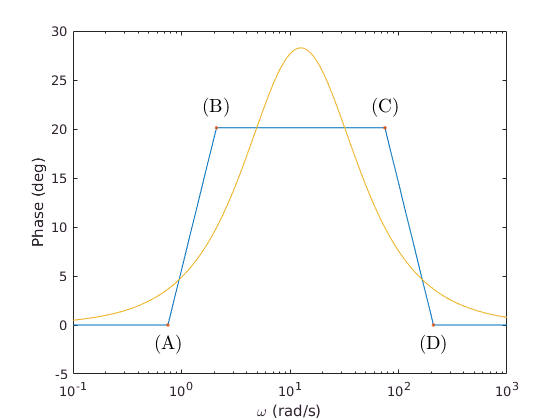

% Fig. 7.6:
figure()

xl = 10.^[-1 3];
yl = [-5 30];

semilogx(wp, phsl,'-', wp, phsl,'.', ...
         w, [phs(:)'])

xlim(xl)
ylim(yl)

text(wp(2), phsl(2)-2, '(A)', 'BackgroundColor', 'white', 'FontSize', 14, 'HorizontalAlignment', 'center','interpreter','latex');
text(wp(3), phsl(3)+2, '(B)', 'BackgroundColor', 'white', 'FontSize', 14, 'HorizontalAlignment', 'center','interpreter','latex');
text(wp(4), phsl(4)+2, '(C)', 'BackgroundColor', 'white', 'FontSize', 14, 'HorizontalAlignment', 'center','interpreter','latex');
text(wp(5), phsl(5)-2, '(D)', 'BackgroundColor', 'white', 'FontSize', 14, 'HorizontalAlignment', 'center','interpreter','latex');

ylabel('Phase (deg)');
xlabel('\omega (rad/s)');

Create a `tf` object to represent the transfer-function in (7.1):

G = tf([28.1 22.4 112.4],[1 5.7 12.81 47.6 7.5 11.25 0])


G =
 
                 28.1 s^2 + 22.4 s + 112.4
  --------------------------------------------------------
  s^6 + 5.7 s^5 + 12.81 s^4 + 47.6 s^3 + 7.5 s^2 + 11.25 s
 
Continuous-time transfer function.



zpk(G)


ans =
 
            28.1 (s^2 + 0.7972s + 4)
  --------------------------------------------
  s (s+5) (s^2 + 0.1s + 0.25) (s^2 + 0.6s + 9)
 
Continuous-time zero/pole/gain model.



Use the provided `basym` function and `bode` to plot the Bode plot and the straight line asymptotes of the magnitude of the frequency response:

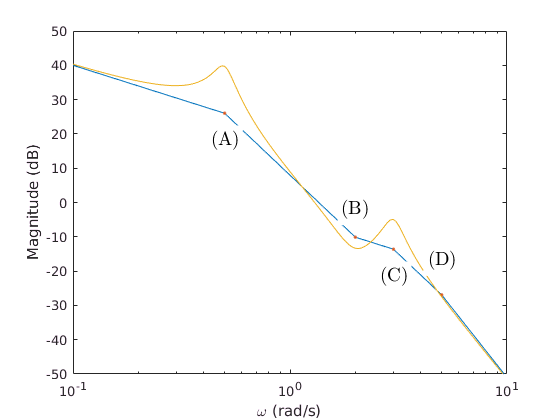

% Fig. 7.7:
figure()

w = logspace(-2,2,300);
[mag,phs] = bode(G, w);
[wl,magl,wp,phsl] = basym(G);

xl = 10.^[-1 1];
yl = [-50 50];

semilogx(wl, magl, '-', wl,magl, '.', ...
         w, 20*log10([mag(:)']))

text(.5, magl(2)-8, '(A)', 'BackgroundColor', 'white', 'FontSize', 14, 'HorizontalAlignment', 'center','interpreter','latex');
text(2, magl(4)+8, '(B)', 'BackgroundColor', 'white', 'FontSize', 14, 'HorizontalAlignment', 'center','interpreter','latex');
text(3, magl(6)-8, '(C)', 'BackgroundColor', 'white', 'FontSize', 14, 'HorizontalAlignment', 'center','interpreter','latex');
text(5, magl(8)+10, '(D)', 'BackgroundColor', 'white', 'FontSize', 14, 'HorizontalAlignment', 'center','interpreter','latex');

xlim(xl)
ylim(yl)

ylabel('Magnitude (dB)');
xlabel('\omega (rad/s)');

and then plot the phase of the frequency response:

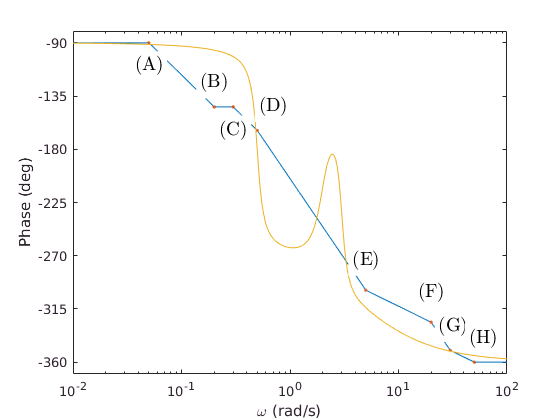

% Fig. 7.8:
figure()

xl = 10.^[-2 2];
yl = [-370 -80];

semilogx(wp, phsl,'-', wp, phsl,'.', ...
         w, [phs(:)'])

xlim(xl)
ylim(yl)

text(wp(2), phsl(2)-20, '(A)', 'BackgroundColor', 'white', 'FontSize', 14, 'HorizontalAlignment', 'center','interpreter','latex');
text(wp(3), phsl(3)+20, '(B)', 'BackgroundColor', 'white', 'FontSize', 14, 'HorizontalAlignment', 'center','interpreter','latex');
text(wp(4), phsl(4)-20, '(C)', 'BackgroundColor', 'white', 'FontSize', 14, 'HorizontalAlignment', 'center','interpreter','latex');
text(wp(5)+.2, phsl(5)+20, '(D)', 'BackgroundColor', 'white', 'FontSize', 14, 'HorizontalAlignment', 'center','interpreter','latex');
text(wp(6), phsl(6)+25, '(E)', 'BackgroundColor', 'white', 'FontSize', 14, 'HorizontalAlignment', 'center','interpreter','latex');
text(wp(8)+2, phsl(8)+20, '(G)', 'BackgroundColor', 'white', 'FontSize', 14, 'HorizontalAlignment', 'center','interpreter','latex');
text(wp(7), phsl(7)+25, '(F)', 'BackgroundColor', 'white', 'FontSize', 14, 'HorizontalAlignment', 'center','interpreter','latex');
text(wp(9)+10, phsl(9)+20, '(H)', 'BackgroundColor', 'white', 'FontSize', 14, 'HorizontalAlignment', 'center','interpreter','latex');

set(gca,'YTick',[-360 -315 -270 -225 -180 -135 -90]);

ylabel('Phase (deg)');
xlabel('\omega (rad/s)');

## 7.2 Non-Minimum Phase Systems

Create `tf` objects to represent the systems $G_1$,$G_2$ and $G_3$ from (7.2):

G1 = tf([1 1], [1 1 1])


G1 =
 
     s + 1
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.



G2 = tf([-1 1], [1 1 1])


G2 =
 
    -s + 1
  -----------
  s^2 + s + 1
 
Continuous-time transfer function.



G3 = tf(conv([-1 1],[-1 1]), [1 2 2 1])


G3 =
 
      s^2 - 2 s + 1
  ---------------------
  s^3 + 2 s^2 + 2 s + 1
 
Continuous-time transfer function.



and plot the Bode plot and the straight-line asymptotes of the magnitude and phase of the frequency response:

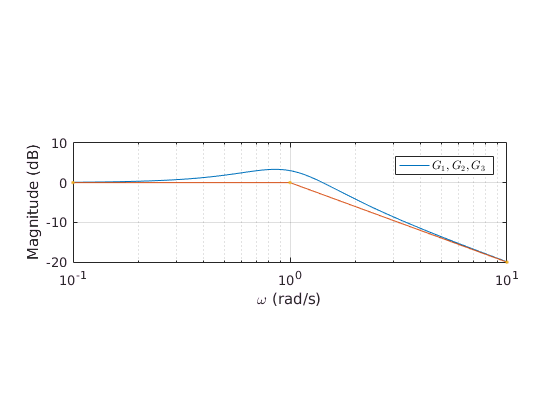

w = logspace(-1,1,100);
[mag1,phs1] = bode(G1, w);
[mag2,phs2] = bode(G2, w);
[mag3,phs3] = bode(G3, w);

phs2 = phs2 - 360;  % matlab gets phase wrapped up!
phs3 = phs3 - 360;  % matlab gets phase wrapped up!

[wl1,magl1,wp1,phsl1] = basym(G1);
[wl2,magl2,wp2,phsl2] = basym(G2);
[wl3,magl3,wp3,phsl3] = basym(G3);

% Fig. 7.9 (a)
figure()

xl = [-1 1];
yl1 = [-20 10];

semilogx(w, 20*log10([mag1(:)']), ...
         wl1, magl1, '-', ...
         wl1, magl1, '.');

xlim(10.^xl);
ylim(yl1);
grid

set(gca, 'YTick', [-20 -10 0 10]);
set(gca, 'PlotBoxAspectRatio', [1 .275 1]);

l = legend('$G_1, G_2, G_3$~', 'Location', 'NorthEast');
set(l, 'interpreter', 'latex');
ylabel('Magnitude (dB)');
xlabel('\omega (rad/s)');

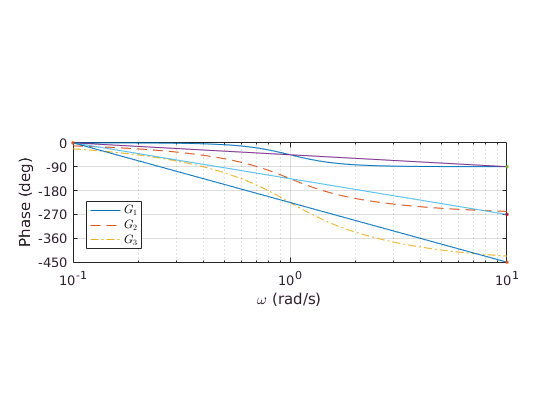


% Fig. 7.9 (b)
figure()

yl2 = [-450 0];

h = semilogx(w, phs1(:)', '-', ...
             w, phs2(:), '--', ...
             w, phs3(:)', '-.', ...
             wp1, phsl1, '-', ...
             wp1, phsl1, '.', ...
             wp2, phsl2, '-', ...
             wp2, phsl2, '.', ...
             wp3, phsl3, '-', ...
             wp3, phsl3, '.');

xlim(10.^xl);
ylim(yl2);

set(gca, 'YTick', [-450 -360 -270 -180 -90 0 90 180 270 360]);
set(gca, 'PlotBoxAspectRatio', [1 .275 1]);

grid

l = legend('$G_1$','$G_2$', '$G_3$', 'Location', 'SouthWest');
set(l, 'interpreter', 'latex');
ylabel('Phase (deg)');
xlabel('\omega (rad/s)');

Then calculate and plot the step responses:

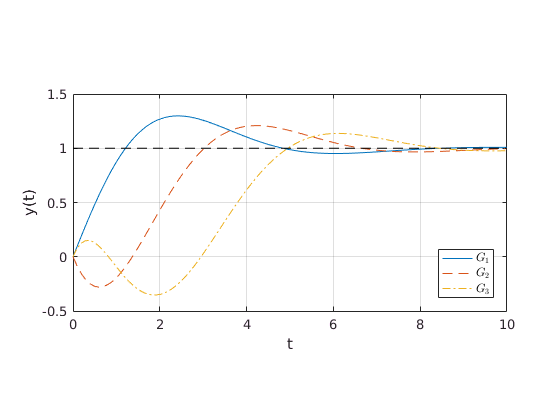

% Fig. 7.10:
figure()

T = 10;
[y1, t1] = step(G1, T);
[y2, t2] = step(G2, T);
[y3, t3] = step(G3, T);

plot(t1, y1, '-', t2, y2, '--', t3, y3, '-.', ...
     [0 T], [1 1], '--k');

xlim([0 T]);
ylim([-0.5 1.5]);
grid
pbaspect([1 1/2 1]);

l = legend('$G_1$', '$G_2$', '$G_3$', 'Location', 'SouthEast');
set(l, 'interpreter', 'latex');
xlabel('t')
ylabel('y(t)')

## 7.3 Polar Plots

Create a tf object to represent $G(s) = \frac{1}{s + 1}$:

G = tf(1,[1 1])


G =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



Plot the Bode plot and the straight-line asymptotes of the magnitude and phase of the frequency response:

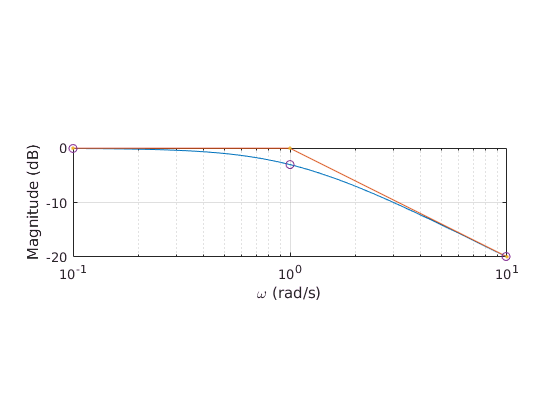

xl = [-1 1];
ylm = [-20 0];
ylp = [-90 0];

[mag,phs,w] = bode(G, {10^xl(1), 10^xl(2)});
[wl,magl,wp,phsl] = basym(G);

we = [0 inf];
fe = freqresp(G,we);

wr = [0.1 1 9.9];
fr = freqresp(G,wr);

% Fig. 7.12 (a)
figure()

semilogx(w, 20*log10(mag(:)'), ...
         wl, magl, '-', ...
         wl, magl, '.', ...
         wr, 20*log10(abs(fr(:))), 'o', ...
         we, 20*log10(abs(fe(:))), 'x');

set(gca,'YTick',[-20 -10 0]);
grid on

xlim(10.^xl);
ylim(ylm);
pbaspect([1 1/4 1]);

ylabel('Magnitude (dB)');
xlabel('\omega (rad/s)');

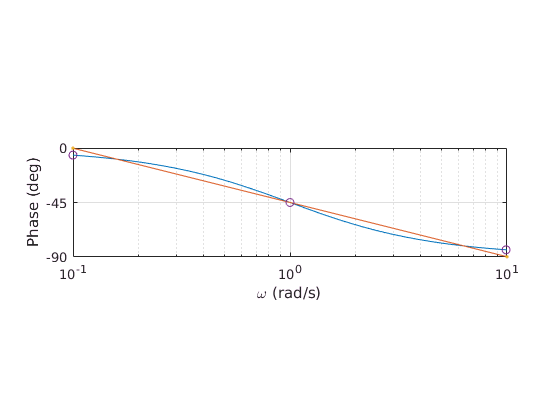


% Fig. 7.12 (b)
figure()

semilogx(w, phs(:), ...
         wp, phsl, '-', ...
         wp, phsl, '.', ...
         wr, 180*phase(fr(:))/pi, 'o', ...
         we, 180*phase(fe(:))/pi, 'x');

set(gca,'YTick',[-90 -45 0]);
grid on

xlim(10.^xl);
ylim(ylp);

ylabel('Phase (deg)');
xlabel('\omega (rad/s)');

pbaspect([1 1/4 1]);

and use `nyquist`:

[re,im] = nyquist(G);

to evaluate the frequency response. When called without output arguments, `nyquist` produces a Nyquist plot:

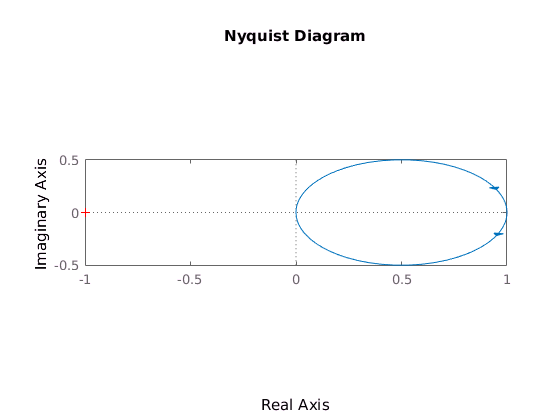

nyquist(G)

Use the output of `nyquist` to produce the following polar plot:

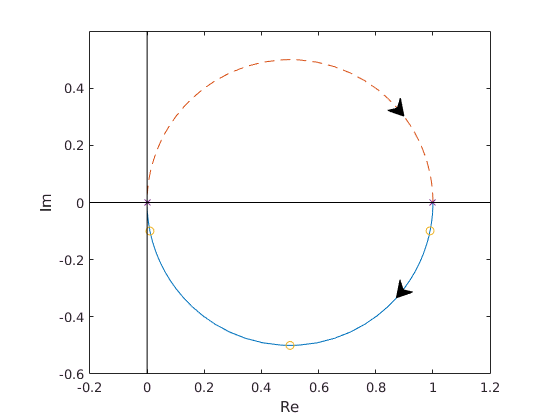

% Fig. 7.12 (c)
figure()

xl = [-.2 1.2];
yl = [-.6 .6];

plot(re(:), im(:), '-', ...
     re(:), -im(:), '--', ...
     real(fr(:)), imag(fr(:)), 'o', ...
     real(fe(:)), imag(fe(:)), 'x', ...
     xl, [0 0], '-k', ...
     [0 0], yl, '-k')

xlim(xl)
ylim(yl)

i = floor(7 * length(re) / 16);
h = arrow([re(i), im(i)], [re(i+1), im(i+1)], ...
          'TipAngle', 30, 'BaseAngle', 60);

h = arrow([re(i+1), -im(i+1)], [re(i), -im(i)], ...
          'TipAngle', 30, 'BaseAngle', 60);

xlabel('Re');
ylabel('Im');

pbaspect([1 diff(ylim)/diff(xlim) 1]);

## 7.4 The Argument Principle

Samples points on the contours $C_1$,$C_2$ and $C_3$:

x = linspace(-1,1,100);
C1 = 1.5*[(x-j) (1+j*x) (-x+j) (-1-j*x)];

theta = linspace(0,2*pi,200);
C2 = -.5+.9*exp(-j*theta);

C3 = .5 + 1*j + .75*exp(j*theta);

and plot the contours. Use the function `arrow` to indicate the direction of travel:

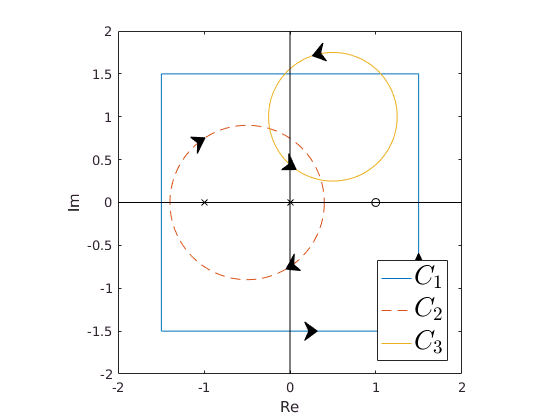

% Fig. 7.13(a)
figure()

xl = [-2 2];
yl = [-2 2];

plot(real(C1), imag(C1), '-', ...
     real(C2), imag(C2), '--', ...
     real(C3), imag(C3), '-', ...
     [0 -1], [0 0], 'kx', ...
     [1], [0], 'ko', ...
     xl, [0 0], '-k', ...
     [0 0], yl, '-k');

i = 60;
arrow([real(C3(i)), imag(C3(i))], [real(C3(i+1)), imag(C3(i+1))], ...
      'TipAngle', 30, 'BaseAngle', 60);

i = 33;
arrow([real(C2(i)), imag(C2(i))], [real(C2(i+1)), imag(C2(i+1))], ...
      'TipAngle', 30, 'BaseAngle', 60);

i = 60;
arrow([real(C1(i)), imag(C1(i))], [real(C1(i+1)), imag(C1(i+1))], ...
      'TipAngle', 30, 'BaseAngle', 60);

i = 130;
arrow([real(C3(i)), imag(C3(i))], [real(C3(i+1)), imag(C3(i+1))], ...
      'TipAngle', 30, 'BaseAngle', 60);

i = 131;
arrow([real(C2(i)), imag(C2(i))], [real(C2(i+1)), imag(C2(i+1))], ...
      'TipAngle', 30, 'BaseAngle', 60);

i = 130;
arrow([real(C1(i)), imag(C1(i))], [real(C1(i+1)), imag(C1(i+1))], ...
      'TipAngle', 30, 'BaseAngle', 60)

xlim(xl)
ylim(yl)

xlabel('Re');
ylabel('Im');

l = legend('$C_1$','$C_2$', '$C_3$', 'Location', 'SouthEast');
set(l, 'interpreter', 'latex', 'FontSize', 20);

pbaspect([1 diff(ylim)/diff(xlim) 1]);

Sample points of the image of the contours $C_1$,$C_2$ and $C_3$, through $G(s)=\frac{s-1}{s^2 + s}$:

G1 = (C1 - 1)./((C1 + 1).*(C1));
G2 = (C2 - 1)./((C2 + 1).*(C2));
G3 = (C3 - 1)./((C3 + 1).*(C3));

Plot the images:

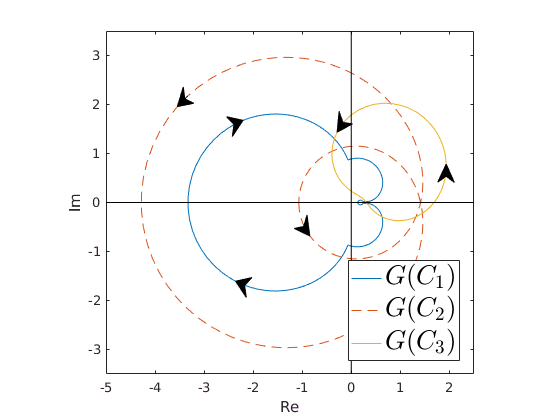

% Fig. 7.13(b)
figure()

xl = [-5 2.5];
yl = [-3.5 3.5];

plot(real(G1), imag(G1), '-', ...
     real(G2), imag(G2), '--', ...
     real(G3), imag(G3), '-', ...
     xl, [0 0], '-k', ...
     [0 0], yl, '-k');

i = 360;
arrow([real(G1(i)), imag(G1(i))], [real(G1(i+1)), imag(G1(i+1))], ...
      'TipAngle', 30, 'BaseAngle', 60);

i = 5;
arrow([real(G2(i)), imag(G2(i))], [real(G2(i+1)), imag(G2(i+1))], ...
      'TipAngle', 30, 'BaseAngle', 60);

i = 140;
hh = arrow([real(G3(i)), imag(G3(i))], [real(G3(i+1)), imag(G3(i+1))], ...
  'TipAngle', 30, 'BaseAngle', 60);

i = 340;
arrow([real(G1(i)), imag(G1(i))], [real(G1(i+1)), imag(G1(i+1))], ...
      'TipAngle', 30, 'BaseAngle', 60);

i = 93;
arrow([real(G2(i)), imag(G2(i))], [real(G2(i+1)), imag(G2(i+1))], ...
      'TipAngle', 30, 'BaseAngle', 60);

i = 120;
arrow([real(G3(i)), imag(G3(i))], [real(G3(i+1)), imag(G3(i+1))], ...
      'TipAngle', 30, 'BaseAngle', 60);

xlim(xl)
ylim(yl)

xlabel('Re');
ylabel('Im');

l = legend('$G(C_1)$','$G(C_2)$', '$G(C_3)$', 'Location', 'SouthEast');
set(l, 'interpreter', 'latex', 'FontSize', 20);

pbaspect([1 diff(ylim)/diff(xlim) 1]);

## 7.5 Stability in the Frequency Domain

Create a tf object to represent $G(s) = \frac{1}{s + 1}$:

G = tf(1,[1 1])


G =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.



and sample points on the image of the contour $\Gamma$ using `nyquist` to calculate the image of the imaginary axis:

rho = 10;
[re,im] = nyquist(G, {1e-3,rho});

theta = linspace(pi/2, -pi/2, 50);
s = rho*exp(j*theta);
f = 1./(s + 1);

and plot the resulting image:

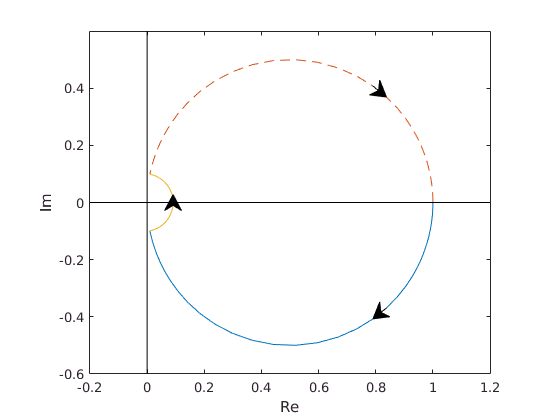

% Fig. 7.16
figure()

xl = [-.2 1.2];
yl = [-.6 .6];

plot(re(:), im(:), '-', ...
     re(:), -im(:), '--', ...
     real(f), imag(f), '-', ...
     xl, [0 0], '-k', ...
     [0 0], yl, '-k')

i = 40;
arrow([re(i), im(i)], [re(i+1), im(i+1)], ...
      'TipAngle', 30, 'BaseAngle', 60);

arrow([re(i+1), -im(i+1)], [re(i), -im(i)], ...
      'TipAngle', 30, 'BaseAngle', 60);

i = 25;
arrow([real(f(i)), imag(f(i))+.025], [real(f(i+1)), imag(f(i+1))+.025], ...
      'TipAngle', 30, 'BaseAngle', 60);

xlim(xl)
ylim(yl)

xlabel('Re');
ylabel('Im');

pbaspect([1 diff(ylim)/diff(xlim) 1]);

Evaluate the image of the imaginary axis for the transfer-function


$$G(s) = \frac{s + 1}{s + 1 + e^{-s}}$$


rho = 200;
omega = logspace(-2,log10(rho),300);
s = j*omega;
f = (s + 1)./(s + 1 + exp(-s));
re = real(f);
im = imag(f);
mag = abs(f);
phs = (180/pi)*phase(f);

and plot the magnitude and phase of the frequency response:

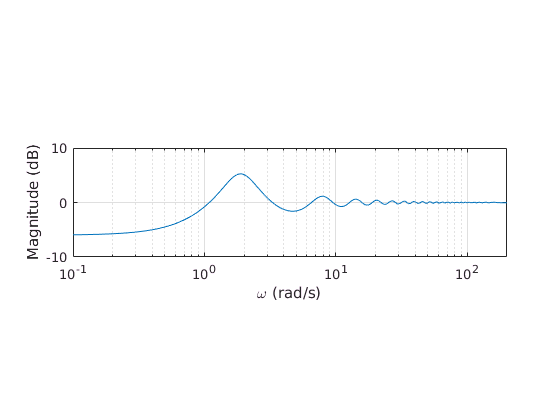

% Fig. 7.17(a):
figure()

semilogx(omega, 20*log10(mag(:)'));
set(gca,'YTick',[-10 0 10]);
grid on

xlim(10.^[-1 log10(rho)]);
pbaspect([1 1/4 1]);

ylabel('Magnitude (dB)');
xlabel('\omega (rad/s)');

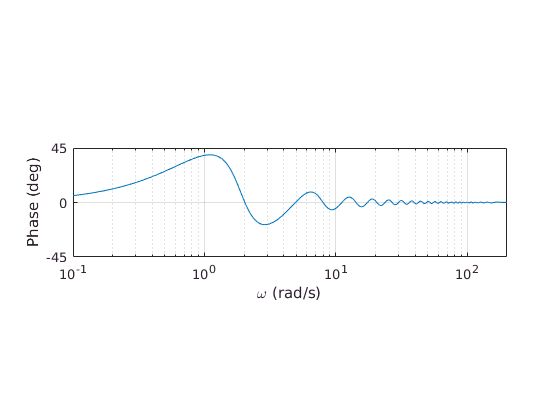


% Fig. 7.17(b):
figure()

semilogx(omega, phs(:));
set(gca,'YTick',[-45 0 45]);
grid on

xlim(10.^[-1 log10(rho)]);
ylim([-45 45]);

ylabel('Phase (deg)');
xlabel('\omega (rad/s)');

pbaspect([1 1/4 1]);

and the polar plot:

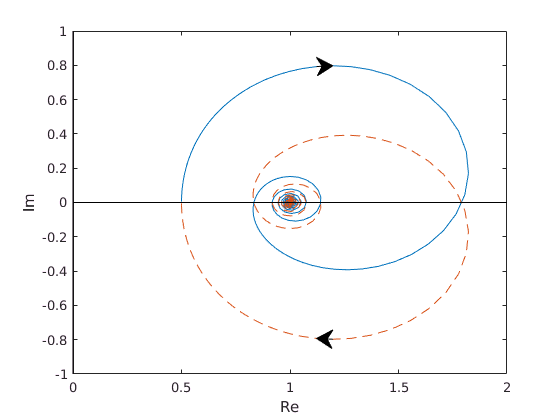

% Fig. 7.17(c)
figure()

xl = [0 2];
yl = [-1 1];

plot(re(:), im(:), ...
     re(:), -im(:), '--', ...
     xl, [0 0], '-k', ...
     [0 0], yl, '-k')

i = 150;
arrow([re(i), im(i)], [re(i+1), im(i+1)], ...
      'TipAngle', 30, 'BaseAngle', 60);

arrow([re(i+1), -im(i+1)], [re(i), -im(i)], ...
      'TipAngle', 30, 'BaseAngle', 60);

xlim(xl)
ylim(yl)

xlabel('Re');
ylabel('Im');

## 7.6 Nyquist Stability Criterion

Create a `tf` object to represent $L(s) = \frac{s-0.5}{s^4+2.5s^3+3s^2+2.5s+1}$:

L = tf([1 -1/2],[1 2.5 3 2.5 1])


L =
 
               s - 0.5
  ---------------------------------
  s^4 + 2.5 s^3 + 3 s^2 + 2.5 s + 1
 
Continuous-time transfer function.



and plot the Nyquist diagram:

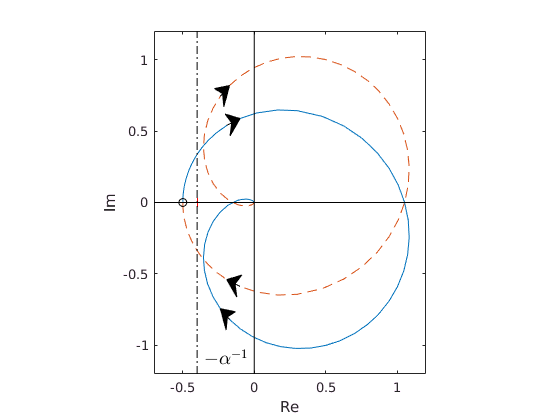

rho = 8;
[re,im] = nyquist(L, {1e-3,rho});

% Fig. 7.19 a
figure()

xl = [-.7 1.2];
yl = [-1.2 1.2];

k = 1/.4;
plot(re(:), im(:), '-', ...
     re(:), -im(:), '--', ...
     -1/k, 0, '+r', ...
     -1/2, 0, 'ok', ...
     [-1/k -1/k], yl, 'k-.', ...
     xl, [0 0], '-k', ...
     [0 0], yl, '-k')

text(-0.35, -1.1, '$-\alpha^{-1}$', 'FontSize', 14, 'interpreter', 'latex');

i = 40;
arrow([re(i), im(i)], [re(i+1), im(i+1)], ...
      'TipAngle', 30, 'BaseAngle', 60);

arrow([re(i+1), -im(i+1)], [re(i), -im(i)], ...
      'TipAngle', 30, 'BaseAngle', 60);

i = 70;
arrow([re(i), im(i)], [re(i+1), im(i+1)], ...
      'TipAngle', 30, 'BaseAngle', 60);

arrow([re(i+1), -im(i+1)], [re(i), -im(i)], ...
      'TipAngle', 30, 'BaseAngle', 60);

xlim(xl)
ylim(yl)

xlabel('Re');
ylabel('Im');

set(gca,'YTick',[-1 -.5 0 .5 1]);
pbaspect([1 diff(ylim)/diff(xlim) 1]);

and the image of $\Gamma$ under $L_\alpha(s) = \frac{1}{\alpha} + L(s)$for $\alpha = 0.4$:

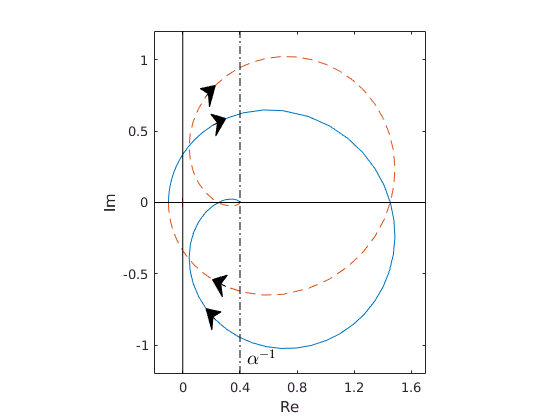

% Fig. 7.19(b)
figure()

xl = [-0.2 1.7];
yl = [-1.2 1.2];

plot(re(:)+1/k, im(:), ...
     re(:)+1/k, -im(:), '--', ...
     0, 0, '+r', ...
     [1/k 1/k], yl, 'k-.', ...
     xl, [0 0], 'k-', ...
     [0 0], yl, '-k')

xlabel('Re');
ylabel('Im');

text(0.45, -1.1, '$\alpha^{-1}$', 'FontSize', 14, 'interpreter', 'latex');

i = 40;
arrow([re(i)+1/k, im(i)], [re(i+1)+1/k, im(i+1)], ...
      'TipAngle', 30, 'BaseAngle', 60);

arrow([re(i+1)+1/k, -im(i+1)], [re(i)+1/k, -im(i)], ...
      'TipAngle', 30, 'BaseAngle', 60);

i = 70;
arrow([re(i)+1/k, im(i)], [re(i+1)+1/k, im(i+1)], ...
      'TipAngle', 30, 'BaseAngle', 60);

arrow([re(i+1)+1/k, -im(i+1)], [re(i)+1/k, -im(i)], ...
      'TipAngle', 30, 'BaseAngle', 60);

xlim(xl)
ylim(yl)

set(gca,'YTick',[-1 -.5 0 .5 1]);
set(gca,'XTick',[0 .4 .8 1.2 1.6]);

pbaspect([1 diff(ylim)/diff(xlim) 1]);

Create a `tf` object to represent $L(s) = \frac{1}{4s(s^2+s/2+1)}$:

L = tf(1/4,[1 1/2 1 0])


L =
 
        0.25
  -----------------
  s^3 + 0.5 s^2 + s
 
Continuous-time transfer function.



and plot the Bode diagram:

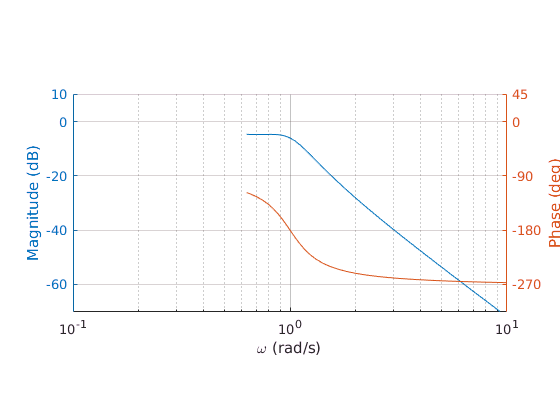

% Fig. 7.21:
figure()

[mag,phs,w] = bode(L, {10^xl(1), 10^xl(2)});

xl = [-1 1];
yl1 = [-70 10];
yl2 = [-315 45];

[haxes,hline1,hline2] = ...
  plotyy(w, 20*log10([mag(:)']), ...
	 w, [phs(:)'], ...
	 'semilogx', 'semilogx');

set(haxes(1), 'XLim', 10.^xl);
set(haxes(2), 'XLim', 10.^xl);
set(haxes(1), 'YLim', yl1);
set(haxes(2), 'YLim', yl2);

set(haxes, 'Box', 'off');
set(haxes, 'YGrid', 'on');
set(haxes, 'XGrid', 'on');

set(haxes(1), 'YTick', [-60 -40 -20 0 10]);
set(haxes(2), 'YTick', [-270 -180 -90 0 45]);

set(haxes, 'PlotBoxAspectRatio', [1 1/2 1]);

ylabel(haxes(1), 'Magnitude (dB)');
ylabel(haxes(2), 'Phase (deg)');
xlabel(haxes(1), '\omega (rad/s)');

and the Nyquist diagram:

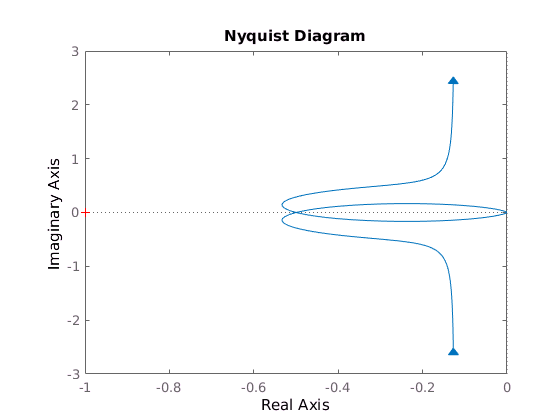

% Fig. 7.22 (a)
figure()

nyquist(L,{.1,10})

and calculate the margins:

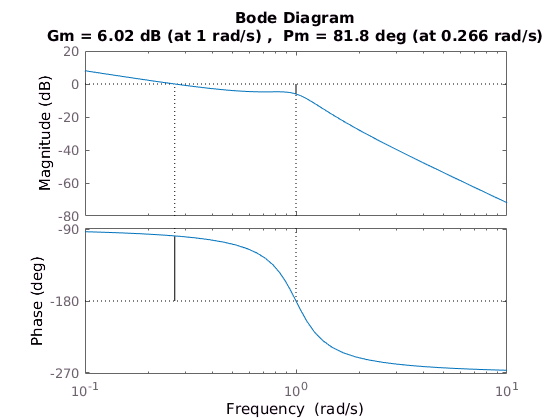

margin(L)

## 7.8 Control of the Simple Pendulum - Part II

Create tf objects to represent the pendulum linearized about the stable and the unstable equlibria:

% Pendulum parameters
m = 0.5

m = 0.5000

l = 0.3

l = 0.3000

r = l/2

r = 0.1500

b = 0

b = 0

g = 9.8

g = 9.8000

J = m*l^2/12

J = 0.0038

Jr = (J+m*r^2)

Jr = 0.0150


% models linearized around equilibria
Gpi = tf(1/Jr, [1, b/Jr, -m*r*g/Jr])


Gpi =
 
   66.67
  --------
  s^2 - 49
 
Continuous-time transfer function.



G0 = tf(1/Jr, [1, b/Jr, m*r*g/Jr])


G0 =
 
   66.67
  --------
  s^2 + 49
 
Continuous-time transfer function.



Create the loop transfer-functions with the addition of an integrator:

L0 = G0 * tf(1,[1 0])


L0 =
 
    66.67
  ----------
  s^3 + 49 s
 
Continuous-time transfer function.



Lpi = Gpi * tf(1,[1 0])


Lpi =
 
    66.67
  ----------
  s^3 - 49 s
 
Continuous-time transfer function.



and plot the combined Bode diagrams:

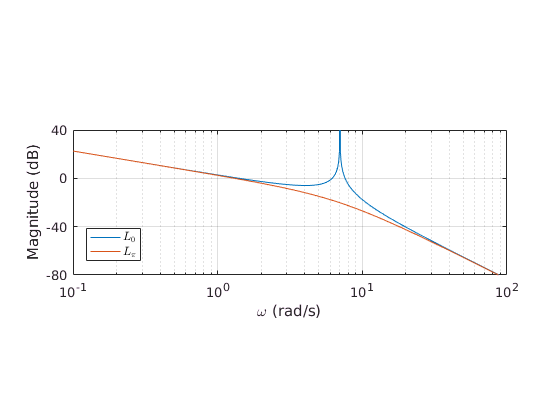

xl = [-1 2];
yl1 = [-80 40];
yl2 = [-360 180];

[wn,Z] = damp(L0);
wn = wn(2);

[magL0,phsL0,w] = bode(L0, {10^xl(1), 10^xl(2)});
ind = find(abs(w - wn) < 1e-2);
phsL0(ind(1)+1) = nan;

[magLpi,phsLpi] = bode(Lpi, w);

% Fix phase
phsL0 = phsL0;
phsLpi = phsLpi+360;

% Fig. 7.25 (a):
figure()

semilogx(w, 20*log10([magL0(:)'; magLpi(:)']));

xlim(10.^xl);
ylim(yl1);
grid on

set(gca, 'YTick', [-80 -40 0 40]);
set(gca, 'PlotBoxAspectRatio', [1 1/3 1]);

l = legend('$L_0$', '$L_\pi$', 'Location', 'SouthWest');
set(l, 'interpreter', 'latex');
ylabel('Magnitude (dB)');
xlabel('\omega (rad/s)');

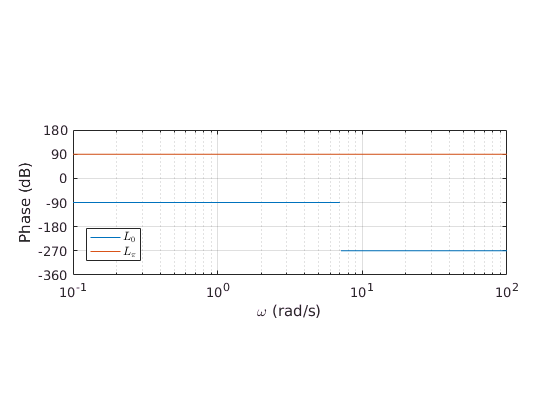


% Fig. 7.25 (b):
figure()

semilogx(w, ([phsL0(:)'; phsLpi(:)']));

xlim(10.^xl);
ylim(yl2);
grid on 

set(gca, 'YTick', [-360 -270 -180 -90 0 90 180]);
set(gca, 'PlotBoxAspectRatio', [1 1/3 1]);

l = legend('$L_0$', '$L_\pi$', 'Location', 'SouthWest');
set(l, 'interpreter', 'latex');
ylabel('Phase (dB)');
xlabel('\omega (rad/s)');

Reconstruct controller $C_6$ from Section 6.5:

C6 = zpk([-6.855, -0.9573], [0, -21], 3.8321)


C6 =
 
  3.8321 (s+6.855) (s+0.9573)
  ---------------------------
           s (s+21)
 
Continuous-time zero/pole/gain model.



create the loop transfer-function:

Lpi6 = C6*Gpi


Lpi6 =
 
  255.47 (s+6.855) (s+0.9573)
  ---------------------------
     s (s+21) (s+7) (s-7)
 
Continuous-time zero/pole/gain model.



and calculate the margins:

% Margins
[gmpi,pmpi,wgmpi,wpmpi] = margin(Lpi6);
Spi = feedback(1,Lpi6);
sm = 1/norm(Spi,inf);

% Gain Margin in dB (G_M)
20*log10(gmpi)

ans = -4.0751


% Phase Margin in deg (phi_M)
pmpi

pmpi = 23.0609


% Stability Margin (S_M)
sm

sm = 0.3989

Plot the Bode diagram combined with $L_\pi$ and $G_\pi$:

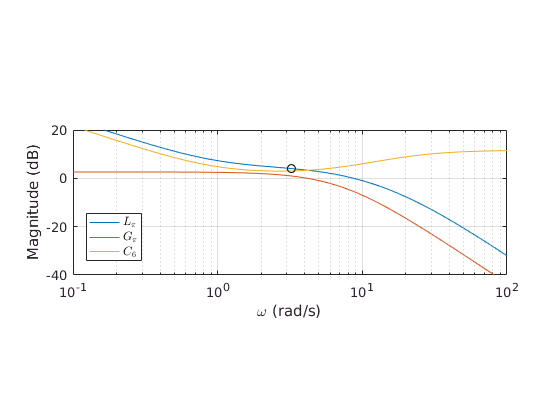

[magGpi,phsGpi] = bode(Gpi, w);
[magLpi6,phsLpi6] = bode(Lpi6, w);
[magC6,phsC6] = bode(C6, w);

% Fix phase
phsGpi = phsGpi+360;
phsLpi6 = phsLpi6+360;

% Fig. 7.26 (a):
figure()

xl = [-1 2];
yl1 = [-40 20];
yl2 = [-90 270];

semilogx(w, 20*log10([magLpi6(:)'; magGpi(:)'; magC6(:)']), ...
         wgmpi, -20*log10(abs(gmpi)), 'ok')

xlim(10.^xl);
ylim(yl1);
grid on

set(gca, 'YTick', [-40 -20 0 20]);
set(gca, 'PlotBoxAspectRatio', [1 1/3 1]);

l = legend('$L_\pi$', '$G_\pi$', '$C_6$', 'Location', 'SouthWest');
set(l, 'interpreter', 'latex');
ylabel('Magnitude (dB)');
xlabel('\omega (rad/s)');

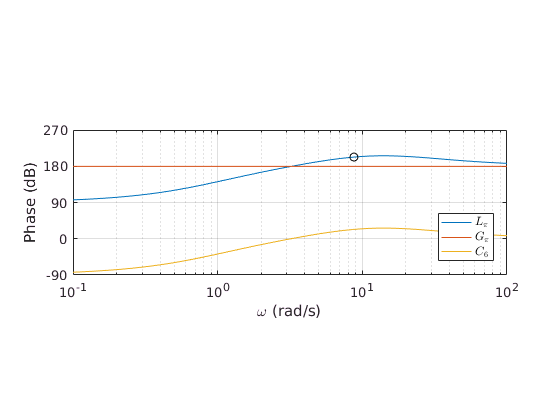


% Fig. 7.26 (b):
figure()

semilogx(w, ([phsLpi6(:)'; phsGpi(:)'; phsC6(:)']), ...
         wpmpi, 180+pmpi, 'ko')

xlim(10.^xl);
ylim(yl2);
grid on

set(gca, 'YTick', [-90 0 90 180 270]);
set(gca, 'PlotBoxAspectRatio', [1 1/3 1]);

l = legend('$L_\pi$', '$G_\pi$', '$C_6$', 'Location', 'SouthEast');
set(l, 'interpreter', 'latex');
ylabel('Phase (dB)');
xlabel('\omega (rad/s)');

Plot the Nyquist diagram:

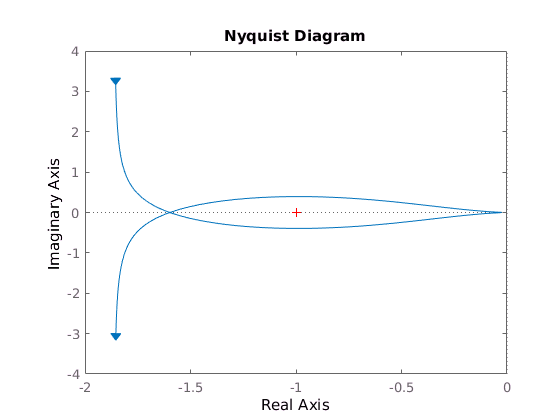

% Fig. 7.27:
figure()

nyquist(Lpi6, {5e-1,1e2});

Construct controller $C_7$:

z1 = 1;
z2 = 5;
pc = 11;
C7 = tf(conv([1 z1],[1 z2]),conv([1 0],[1 pc]));
K = 2/abs(freqresp(C7,wn));
C7 = zpk(K * C7)


C7 =
 
  3.0009 (s+5) (s+1)
  ------------------
       s (s+11)
 
Continuous-time zero/pole/gain model.



Create the loop transfer-function:

Lpi7 = C7*Gpi


Lpi7 =
 
   200.06 (s+5) (s+1)
  --------------------
  s (s+11) (s+7) (s-7)
 
Continuous-time zero/pole/gain model.



and calculate the margins:

% Margins
[gmpi,pmpi,wgmpi,wpmpi] = margin(Lpi7);
Spi = feedback(1,Lpi7);
sm = 1/norm(Spi,inf);

% Gain Margin in dB (G_M)
20*log10(gmpi)

ans = -5.1953


% Phase Margin in deg (phi_M)
pmpi

pmpi = 15.4494


% Stability Margin (S_M)
sm

sm = 0.2660

Plot the Bode diagram combined with $L_\pi$ and $G_\pi$:

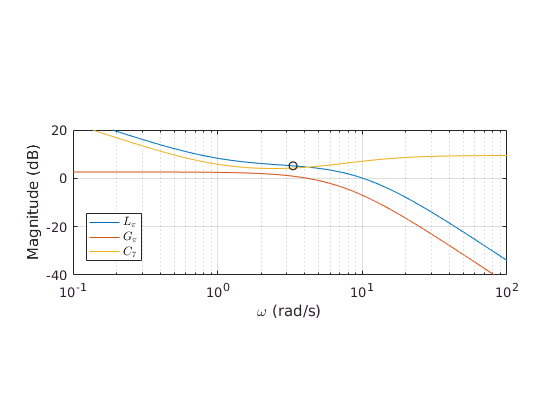

[magLpi7,phsLpi7] = bode(Lpi7, w);
[magC7,phsC7] = bode(C7, w);

% Fix phase
phsLpi7 = phsLpi7+360;

% Bode plots 
xl = [-1 2];
yl1 = [-40 20];
yl2 = [-90 270];

% Fig. 7.29 (a):
figure()

semilogx(w, 20*log10([magLpi7(:)'; magGpi(:)'; magC7(:)']), ...
         wgmpi, -20*log10(abs(gmpi)), 'ok')

xlim(10.^xl);
ylim(yl1);
grid on

set(gca, 'YTick', [-40 -20 0 20]);
set(gca, 'PlotBoxAspectRatio', [1 1/3 1]);

l = legend('$L_\pi$', '$G_\pi$', '$C_7$', 'Location', 'SouthWest');
set(l, 'interpreter', 'latex');
ylabel('Magnitude (dB)');
xlabel('\omega (rad/s)');

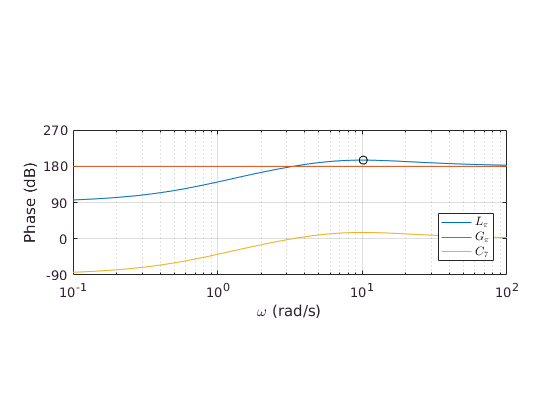


% Fig. 7.29 (b)
figure()

semilogx(w, ([phsLpi7(:)'; phsGpi(:)'; phsC7(:)']), ...
         wpmpi, 180+pmpi, 'ko')

xlim(10.^xl);
ylim(yl2);
grid on

set(gca, 'YTick', [-90 0 90 180 270]);
set(gca, 'PlotBoxAspectRatio', [1 1/3 1]);

l = legend('$L_\pi$', '$G_\pi$', '$C_7$', 'Location', 'SouthEast');
set(l, 'interpreter', 'latex');
ylabel('Phase (dB)');
xlabel('\omega (rad/s)');

Compare the frequency response of the controllers $C_6$ and $C_7$:

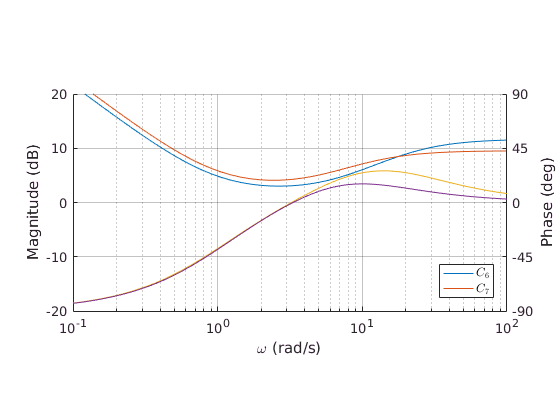

% Fig. 7.28:
figure()

xl = [-1 2];
yl1 = [-20 20];
yl2 = [-90 90];

[magC6,phsC6] = bode(C6, w);
[magC7,phsC7] = bode(C7, w);

[haxes,hline1,hline2] = ...
  plotyy(w, 20*log10([magC6(:)'; magC7(:)']), ...
	 w, [phsC6(:)'; phsC7(:)'], ...
	 'semilogx', 'semilogx');

set(haxes(1), 'XLim', 10.^xl);
set(haxes(2), 'XLim', 10.^xl);
set(haxes(1), 'YLim', yl1);
set(haxes(2), 'YLim', yl2);

set(haxes, 'Box', 'off');
set(haxes, 'YGrid', 'on');
set(haxes, 'XGrid', 'on');

set(haxes(1), 'YTick', [-20 -10 0 10 20]);
set(haxes(2), 'YTick', [-90 -45 0 45 90]);

set(haxes, 'PlotBoxAspectRatio', [1 1/2 1]);

ylabel(haxes(1), 'Magnitude (dB)');
ylabel(haxes(2), 'Phase (deg)');
xlabel(haxes(1), '\omega (rad/s)');

l = legend(hline1, '$C_6$', '$C_7$', 'Location', 'SouthEast');
set(l, 'interpreter', 'latex');

Define the loop transfer-function:

L07 = C7*G0


L07 =
 
  200.06 (s+5) (s+1)
  -------------------
  s (s+11) (s^2 + 49)
 
Continuous-time zero/pole/gain model.



to verify the performance of the controller around the stable equilibrium point.

H07 = feedback(L07,1)


H07 =
 
              200.06 (s+5) (s+1)
  -------------------------------------------
  (s+7.218) (s+0.6305) (s^2 + 3.151s + 219.8)
 
Continuous-time zero/pole/gain model.



damp(H07)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -6.31e-01                 1.00e+00       6.31e-01         1.59e+00    
 -7.22e+00                 1.00e+00       7.22e+00         1.39e-01    
 -1.58e+00 + 1.47e+01i     1.06e-01       1.48e+01         6.35e-01    
 -1.58e+00 - 1.47e+01i     1.06e-01       1.48e+01         6.35e-01    


Calculate the margins:

% Margins
[gm0,pm0,wgm0,wpm0] = margin(L07);
S0 = feedback(1,L07);
sm = 1/norm(S0,inf);

% Gain Margin in dB (G_M)
20*log10(gm0)

ans = Inf


% Phase Margin in deg (phi_M)
pm0

pm0 = 14.0916


% Stability Margin (S_M)
sm

sm = 0.2418

Plot the Bode diagram combined with $L_0$ and $G_0$:Plot the 

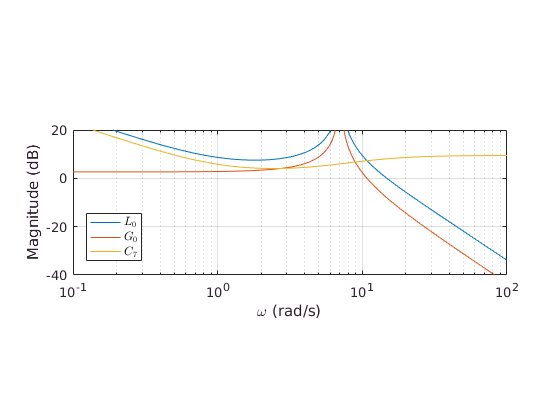

[magL07,phsL07] = bode(L07, w);
ind = find(abs(w - wn) < 1e-2);
phsL07(ind(1)+1) = nan;

[magG0,phsG0] = bode(G0, w);
ind = find(abs(w - wn) < 1e-2);
phsG0(ind(1)+1) = nan;

xl = [-1 2];
yl1 = [-40 20];
yl2 = [-270 90];

% Fig. 7.30 (a):
figure()

semilogx(w, 20*log10([magL07(:)'; magG0(:)'; magC7(:)']), ...
         wgm0, 20*log10(abs(gm0)), 'ok')

xlim(10.^xl);
ylim(yl1);
grid on

set(gca, 'YTick', [-40 -20 0 20]);
set(gca, 'PlotBoxAspectRatio', [1 1/3 1]);

l = legend('$L_0$', '$G_0$', '$C_7$', 'Location', 'SouthWest');
set(l, 'interpreter', 'latex');
ylabel('Magnitude (dB)');
xlabel('\omega (rad/s)');

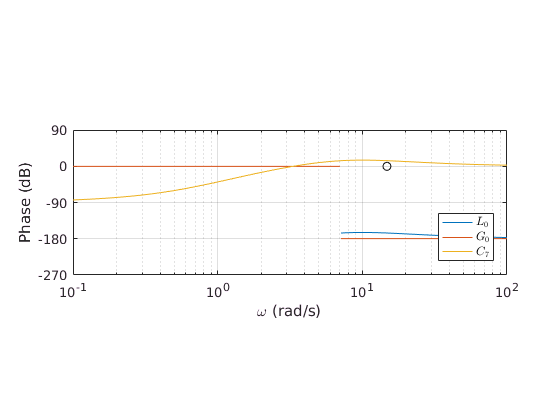


% Fig. 7.30 (b):
figure()

semilogx(w, ([phsL07(:)'; phsG0(:)'; phsC7(:)']), ...
         wpm0, 180/pi*phase(pm0), 'ko')

xlim(10.^xl);
ylim(yl2);
grid on

set(gca, 'YTick', [-360 -270 -180 -90 0 90]);
set(gca, 'PlotBoxAspectRatio', [1 1/3 1]);

l = legend('$L_0$', '$G_0$', '$C_7$', 'Location', 'SouthEast');
set(l, 'interpreter', 'latex');
ylabel('Phase (dB)');
xlabel('\omega (rad/s)');

Plot the Nyquist diagram:

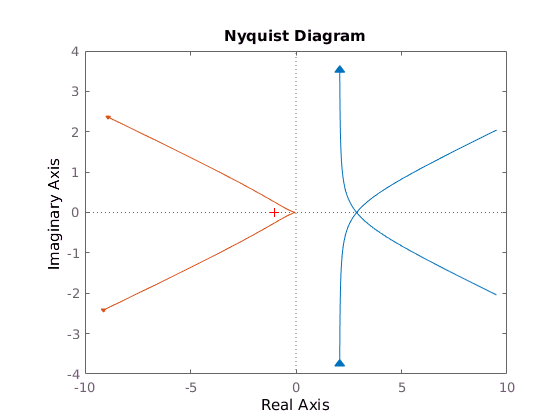

% Fig. 7.31:
figure()

nyquist(L07, {5e-1,6}), hold on
nyquist(L07, {8,1e2}), hold off